different epochs comparison 

clear
clc
close all

x = 0:0.05:(3*pi);
y = sin(x.^2);

algorithms = {'traingd', 'traingda', 'traingdm', 'traingdx', 'traincgf', 'traincgp', 'trainbfg', 'trainlm','trainbr'};


specific_epochs = [100, 200, 300, 400, 500, 600, 700, 800, 900, 1000];

num_algorithms = numel(algorithms);
mse_values = zeros(num_algorithms, 10);



for i = 1:num_algorithms
    for j = 1:10
        net_epoch = feedforwardnet(50,algorithms{i});
        net_epoch.trainParam.epochs = specific_epochs(j);
        [net_epoch, tr_epoch] = train(net_epoch, x, y);
        mse_values(i, j) = tr_epoch.best_tperf;

    end
end



line_styles = {'-', '--', ':', '-.', '-', '--', ':', '-.', '--'};
markers = {'o', 'x', 's', 'd', 'v', '^', '<', '>', '*'};


figure;
hold on;
for i = 1:num_algorithms
    plot(specific_epochs, mse_values(i, :)', 'LineStyle', line_styles{i}, 'Marker', markers{i}, 'DisplayName', algorithms{i});
end
hold off;
title('MSE Over Specific Epochs');
xlabel('Epochs');
ylabel('MSE');
legend('Location', 'best');
grid on;

% prediction output curve-noiseless

epoch = 1000
test_indices = tr_epoch.testInd;
x_test = x(test_indices);
y_test = y(test_indices);

colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k', [0.5, 0.5, 0.5]};

figure;
hold on;
plot(x_test, y_test, 'LineWidth', 2, 'Color', 'k', 'DisplayName', 'Original Test Data');

for i = 1:num_algorithms
    net = feedforwardnet(50)
    net.trainParam.epochs = epoch;  % Set the desired epoch for comparison
    net.trainFcn = algorithms{i};
    [trained_net, ~] = train(net, x, y);
    
    y_test_pred = trained_net(x_test);
    
    plot(x_test, y_test_pred, 'Color', colors{i}, 'DisplayName', algorithms{i});
end

title('Test Data Predictions and Original Test Data');
xlabel('x');
ylabel('y');
legend('Location', 'best');
grid on;
hold off;

noiseless data: generalization-test data set

clear
clc
close all

x = 0:0.05:(3*pi);
y = sin(x.^2);

 % neuron = 10/50



algorithms = {'traingd', 'traingda', 'traingdm', 'traingdx', 'traincgf', 'traincgp', 'trainbfg', 'trainlm', 'trainbr'};


num_specific_run = 20;
num_algorithms = numel(algorithms);
mse_values = zeros(num_algorithms, num_specific_run);
training_times = zeros(num_algorithms, num_specific_run);
best_epochs = zeros(num_algorithms, num_specific_run);

for i = 1:num_algorithms
    for j = 1:num_specific_run
        net = feedforwardnet(200);
        net.trainParam.epochs = 1000;
        net.trainFcn = algorithms{i};
        tic;
        [trained_net, tr] = train(net, x, y);
        training_times(i, j) = toc;
        
        mse_values(i, j) = tr.best_tperf;

    end
end

noiseless_50_mse_values_mean = mean(mse_values');
noiseless_50_training_times_mean = mean(training_times');

noiseless_200_mse_values_mean = mean(mse_values');
noiseless_200_training_times_mean = mean(training_times');

noisy: generalization test dataset

clear
clc
close all

x = 0:0.05:(3*pi);
rng(0);
y = sin(x.^2) + randn(size(sin(x.^2)))*0.2;


algorithms = {'traingd', 'traingda', 'traingdm', 'traingdx', 'traincgf', 'traincgp', 'trainbfg', 'trainlm', 'trainbr'};

num_specific_run = 20;
num_algorithms = numel(algorithms);
mse_values = zeros(num_algorithms, num_specific_run);
training_times = zeros(num_algorithms, num_specific_run);

for i = 1:num_algorithms
    for j = 1:num_specific_run
        net = feedforwardnet(200);
        net.trainParam.epochs = 1000;
  
        
        net.trainFcn = algorithms{i};
        tic;
        [trained_net, tr] = train(net, x, y);
        training_times(i, j) = toc;
       

        mse_values(i, j) = tr.best_tperf;

    end
end


noisy_50_mse_values_mean = mean(mse_values');
noisy_50_training_times_mean = mean(training_times');

noisy_200_mse_values_mean = mean(mse_values');
noisy_200_training_times_mean = mean(training_times');

overfitting validation

trainbr has no validation monitoring

clear
clc
close all

x = 0:0.05:(3*pi);
rng(0);
% y = sin(x.^2) + randn(size(sin(x.^2)))*0.2;
y = sin(x.^2);

algorithms = {'traingd', 'traingda', 'traingdm', 'traingdx', 'traincgf', 'traincgp', 'trainbfg', 'trainlm', 'trainbr'};

num_specific_run = 1;
num_algorithms = numel(algorithms);
mse_values = zeros(num_algorithms, num_specific_run);
r_values = zeros(num_algorithms, num_specific_run);
training_times = zeros(num_algorithms, num_specific_run);
best_epochs = zeros(num_algorithms, num_specific_run);


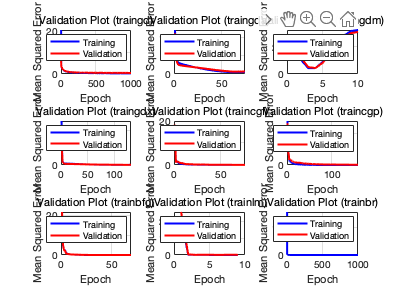

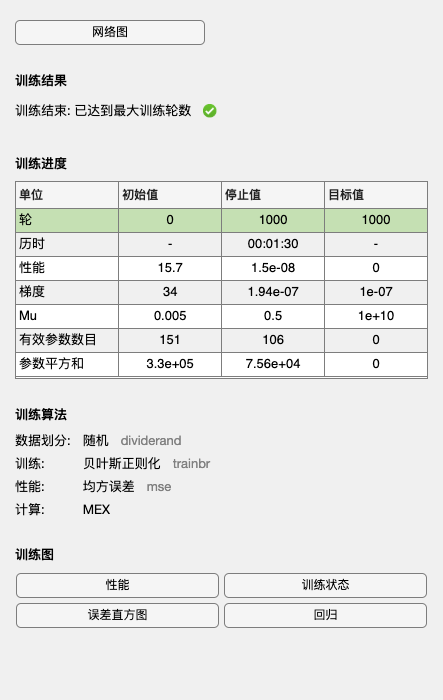

% Create a new figure
figure;

for i = 1:9
    net = feedforwardnet(50);
   
    net.trainParam.epochs = 1000;
    net.trainFcn = algorithms{i};
    tic;
    [trained_net, tr] = train(net, x, y);
    training_times(i) = toc;
    trainPerformance = tr.perf;
    valPerformance = tr.vperf;
    
    % Create a subplot in a 3x3 grid for the current algorithm
    subplot(3, 3, i);
    
    % Plot the performance values
    plot(1:length(trainPerformance), trainPerformance, 'b', 'LineWidth', 2);
    hold on;
    plot(1:length(valPerformance), valPerformance, 'r', 'LineWidth', 2);
    hold off;
    
    % Customize the subplot
    xlabel('Epoch');
    ylabel('Mean Squared Error');
    title(sprintf('Validation Plot (%s)', algorithms{i}));
    legend('Training', 'Validation');
    grid on;
end


% Create a new figure for training plot
figure;
subplot(2, 1, 1);

% Create a new figure for validation plot
figure;
subplot(2, 1, 2);

line_styles = {'-', '--', ':', '-.', '-', '--', ':', '-.', '-', '--'};
line_colors = {'b', 'r', 'g', 'c', 'm', 'y', 'k', 'b', 'r'};
markers = {'o', 's', 'd', 'v', '^', 'x', '+', '*', 'p'};

for i = 1:9
    net = feedforwardnet(50);
   
    net.trainParam.epochs = 1000;
    net.trainFcn = algorithms{i};
    tic;
    [trained_net, tr] = train(net, x, y);
    training_times(i) = toc;
    trainPerformance = tr.perf;
    valPerformance = tr.vperf;
    
    % Plot the training performance in the first subplot
    figure(1);
    subplot(2, 1, 1);
    plot(1:length(trainPerformance), trainPerformance, line_styles{i}, 'Color', line_colors{i}, 'Marker', markers{i}, 'LineWidth', 2);
    hold on;
    
    % Plot the validation performance in the second subplot
    figure(2);
    subplot(2, 1, 2);
    plot(1:length(valPerformance), valPerformance, line_styles{i}, 'Color', line_colors{i}, 'Marker', markers{i}, 'LineWidth', 2);
    hold on;
end

% Adjust vertical spacing between subplots
figure(1);
subplot(2, 1, 1);
ylim auto;
subplot(2, 1, 2);
ylim auto;
linkaxes(findall(gcf,'type','axes'),'y');

% Customize the training subplot
figure(1);
subplot(2, 1, 1);
xlabel('Epoch');
ylabel('Mean Squared Error');
title('Training Plot');
legend(algorithms);
grid on;

% Customize the validation subplot
figure(2);
subplot(2, 1, 2);
xlabel('Epoch');
ylabel('Mean Squared Error');
title('Validation Plot');
legend(algorithms);
grid on;

